# EN3551 Assignment 1

## Detecting Harmonics in Noisy Data and Signal Interpolation using DFT

### T.L Abeygunathilaka - 200003P

## Harmonic Detection

**1.**

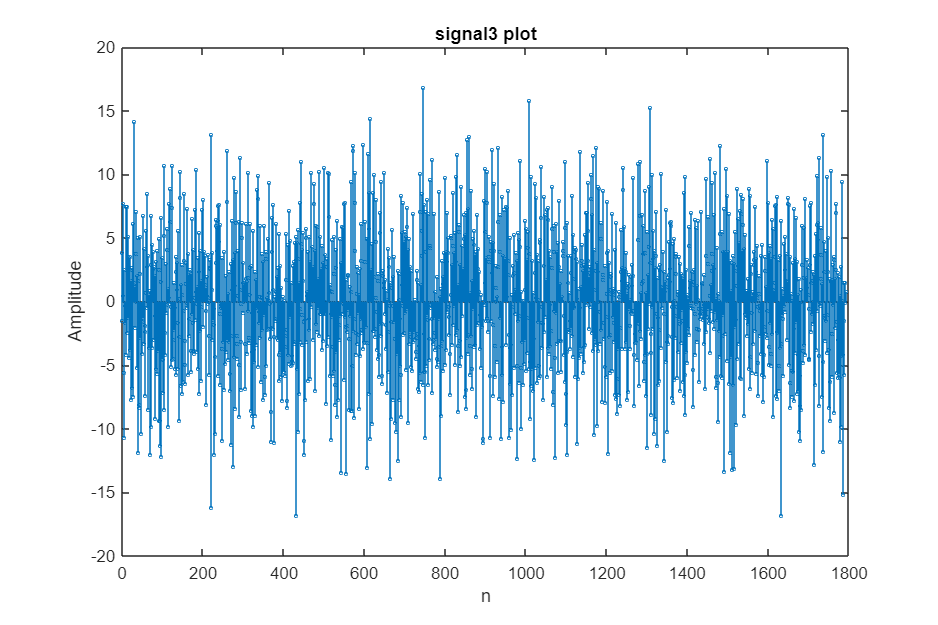

load('signal3.mat', 'xn_test');
figure('Position', [100, 100,750, 500]);
stem(xn_test, 'MarkerSize', 2);
xlabel('n');
ylabel('Amplitude');
title('signal3 plot');

**2.**

% Construct subsets
S1 = xn_test(1:128);
S2 = xn_test(1:256);
S3 = xn_test(1:512);
S4 = xn_test(1:1024);
S5 = xn_test(1:1792);

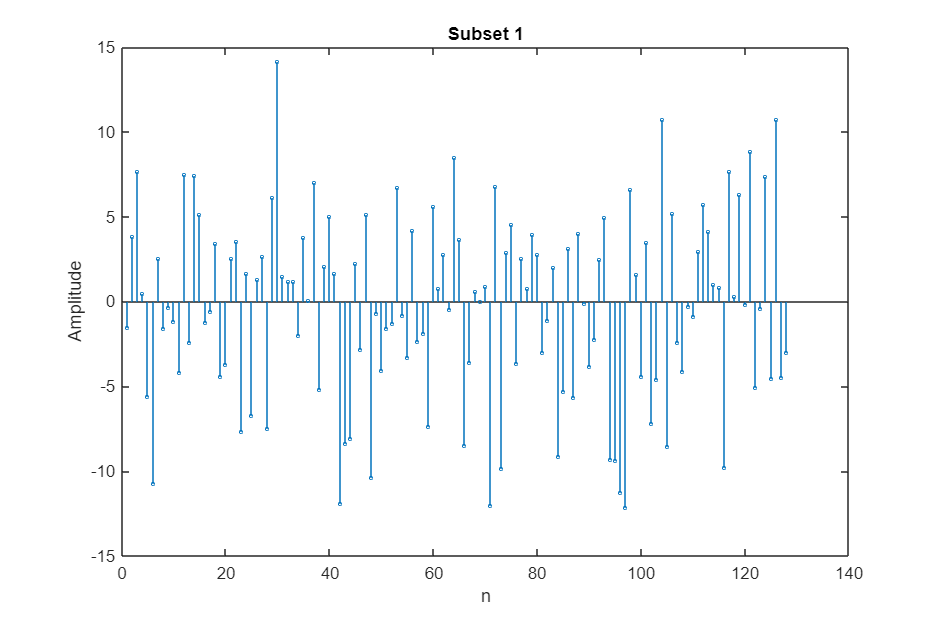

% Plot subset 1
stem(S1, 'MarkerSize', 2);
xlabel('n');
ylabel('Amplitude');
title('Subset 1');

This subset includes first 128 samples.

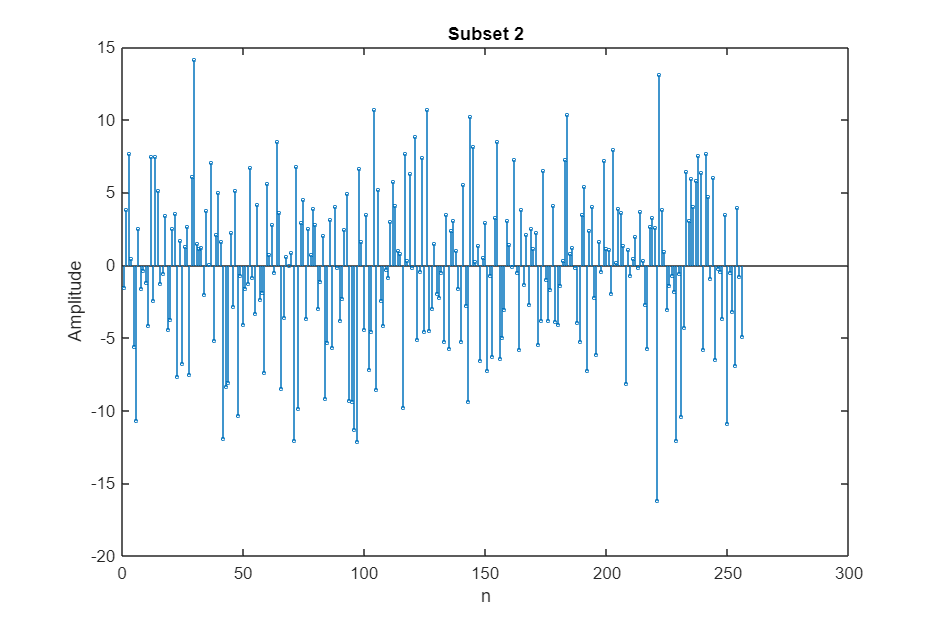


stem(S2, 'MarkerSize', 2);
xlabel('n');
ylabel('Amplitude');
title('Subset 2');

This subset includes first 256 samples.

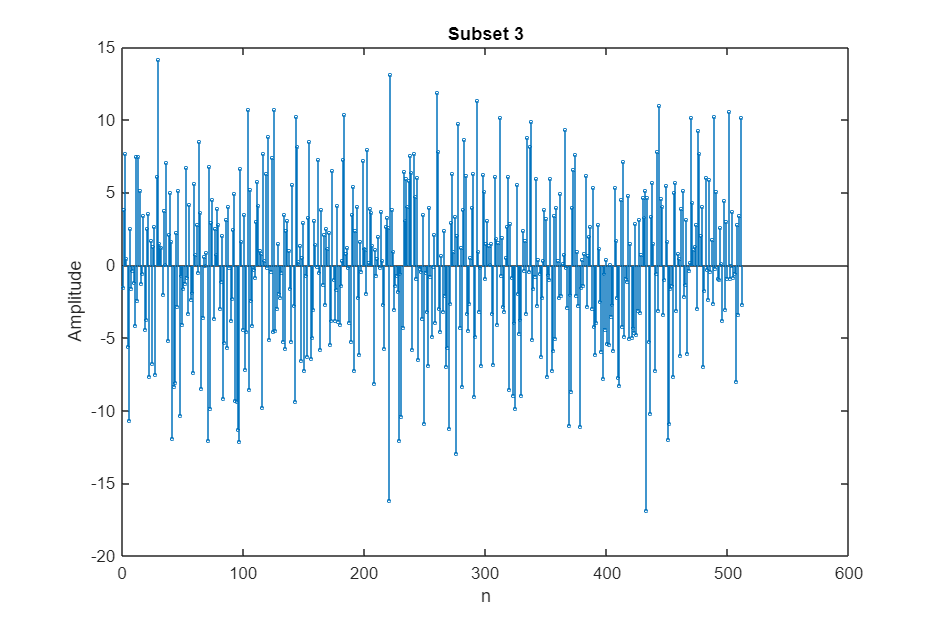


stem(S3, 'MarkerSize', 2);
xlabel('n');
ylabel('Amplitude');
title('Subset 3');

This subset includes first 512 samples.

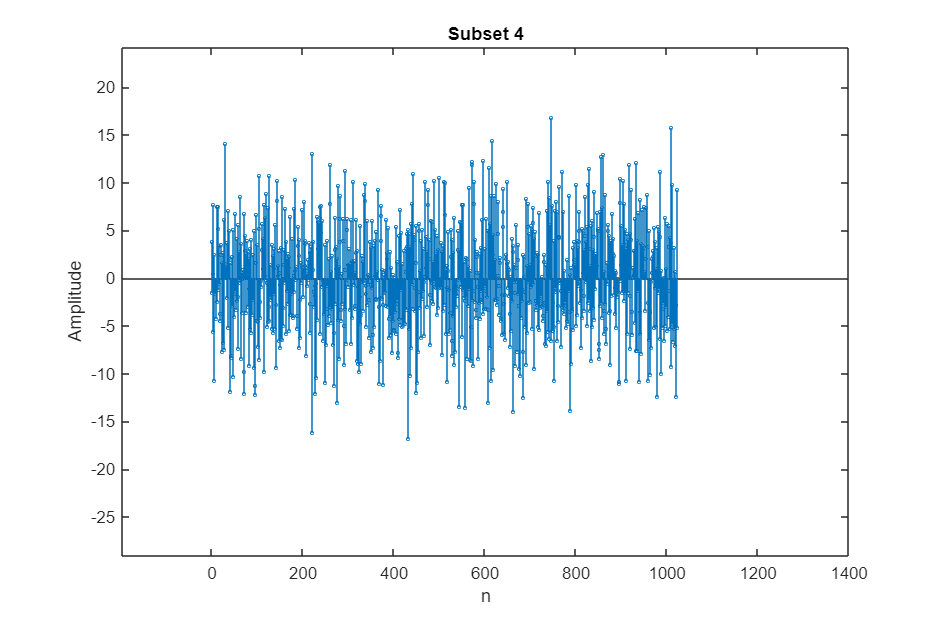


stem(S4, 'MarkerSize', 2);
xlabel('n');
ylabel('Amplitude');
title('Subset 4');

xlim([-197 1400])
ylim([-29.1 24.2])

This subset includes first 1024 samples.

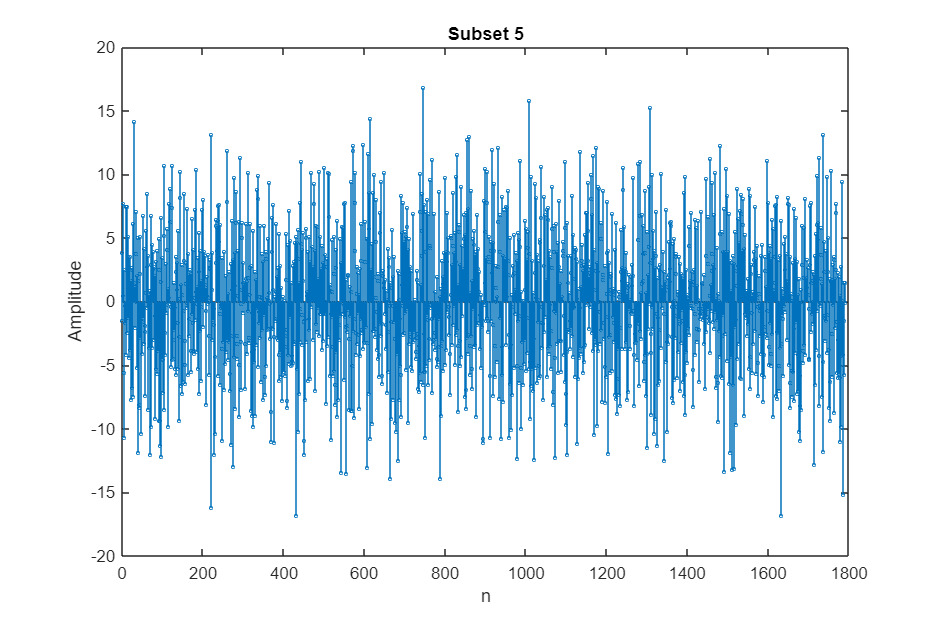


stem(S5, 'MarkerSize', 2);
xlabel('n');
ylabel('Amplitude');
title('Subset 5');

This subset includes all the 1792 samples.

**3.**

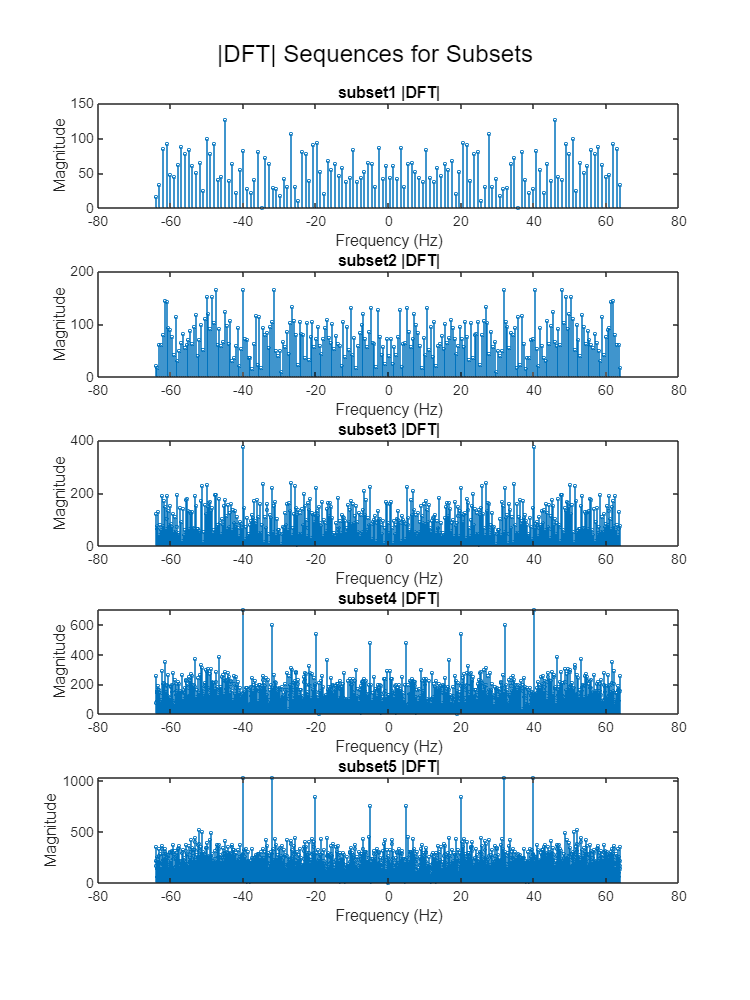

f = 128;

% DFT calculation for each subset
DFT_S1 = fftshift(fft(S1));
DFT_S2 = fftshift(fft(S2));
DFT_S3 = fftshift(fft(S3));
DFT_S4 = fftshift(fft(S4));
DFT_S5 = fftshift(fft(S5));

% create frequency domain
freq1 = linspace(-f/2, f/2, length(S1));
freq2 = linspace(-f/2, f/2, length(S2));
freq3 = linspace(-f/2, f/2, length(S3));
freq4 = linspace(-f/2, f/2, length(S4));
freq5 = linspace(-f/2, f/2, length(S5));

figure('Position', [100, 100, 1500, 2000]);
subplot(5, 1, 1);
stem(freq1, abs(DFT_S1), 'MarkerSize', 2);
title('subset1 |DFT|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(5, 1, 2);
stem(freq2, abs(DFT_S2), 'MarkerSize', 2);
title('subset2 |DFT|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(5, 1, 3);
stem(freq3, abs(DFT_S3), 'MarkerSize', 2);
title('subset3 |DFT|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(5, 1, 4);
stem(freq4, abs(DFT_S4), 'MarkerSize', 2);
title('subset4 |DFT|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

subplot(5, 1, 5);
stem(freq5, abs(DFT_S5), 'MarkerSize', 2);
title('subset5 |DFT|');
xlabel('Frequency (Hz)');
ylabel('Magnitude');

sgtitle('|DFT| Sequences for Subsets');

**4.**

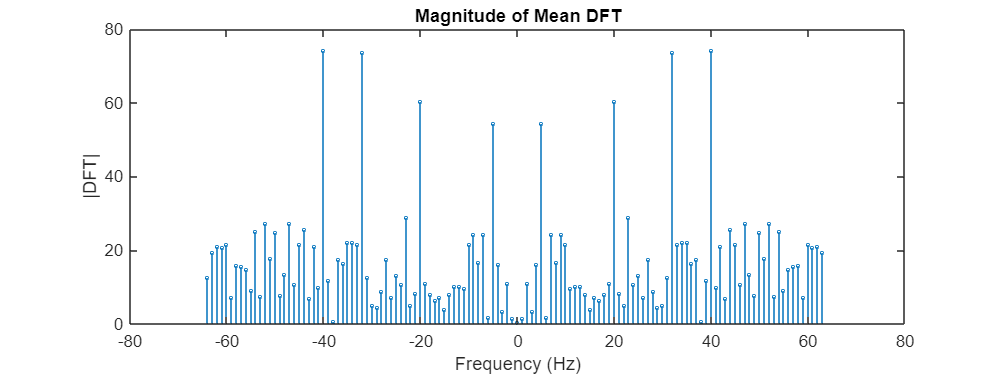

% parameters for dividing the signal
K = 128;  
L = 14;   
subsets = cell(1, L);

% Partition the input signal into L subsets
for i = 0:L-1
    start = (i) * K + 1;
    end_in = (i+1) * K;
    subsets{i+1} = xn_test(start:end_in);
end

% Apply dft for subsets
dft_subsets = cell(1, L);
for i = 0:L-1
    dft_subsets{i+1} = fftshift(fft(subsets{i+1},K));
end
% Calculate the arithmetic mean
mean = zeros(1, K);  

for i = 1:L
    mean = mean + dft_subsets{i};
end
mean = mean / L;

freq = linspace((-f)/2, f/2 -1, K);

% Plot the magnitude of the mean DFT
figure('Position', [100, 100, 800, 300]);
stem(freq, abs(mean), 'MarkerSize', 2);
title('Magnitude of Mean DFT');
xlabel('Frequency (Hz)');
ylabel('|DFT|');

[~, peaks] = findpeaks(abs(mean), 'MinPeakHeight', 40); 

% Convert peak indices to corresponding freq
peak_freq = freq(peaks);

% Display the freq corresponding to the peaks
disp('frequencies of the peaks:');

frequencies of the peaks:


disp(peak_freq);

   -40   -32   -20    -5     5    20    32    40



**5.**

## Lowest L with clearly visible peaks

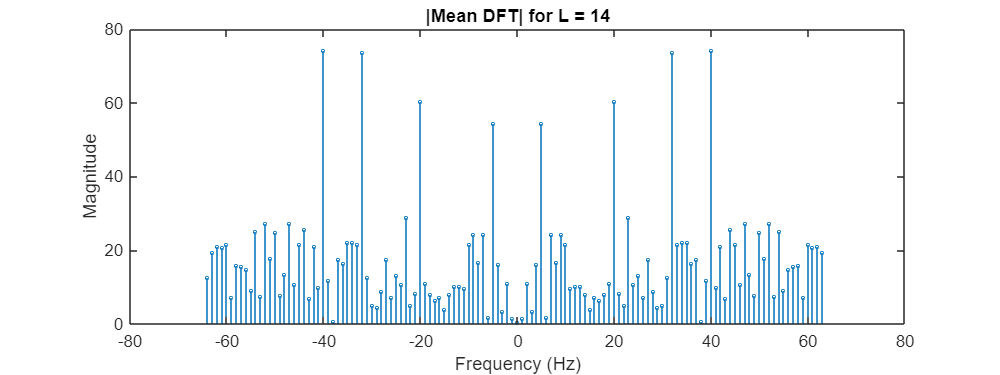

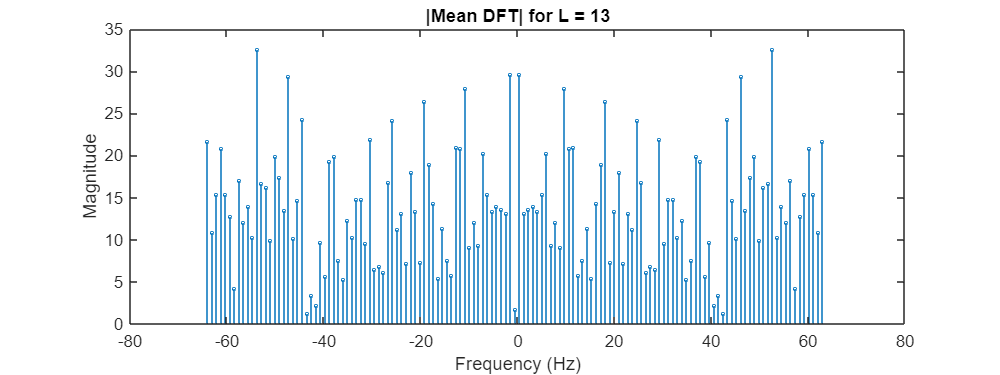

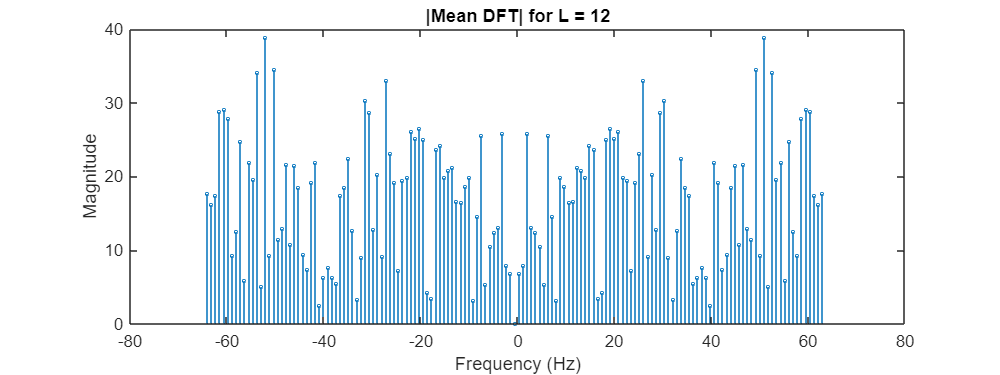

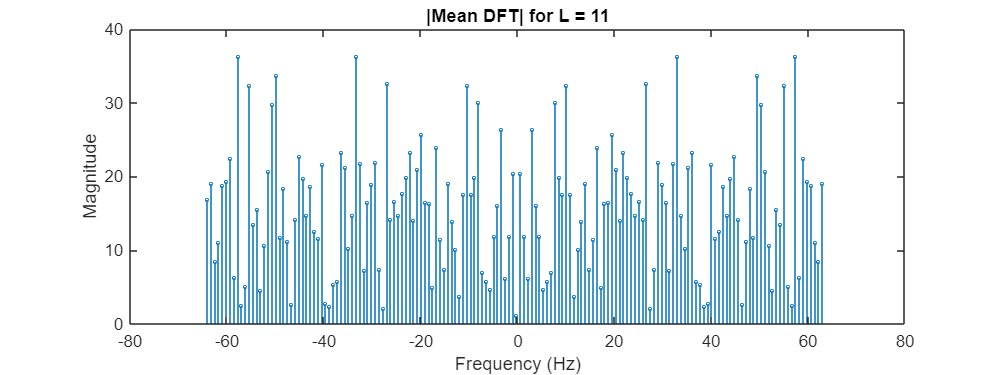

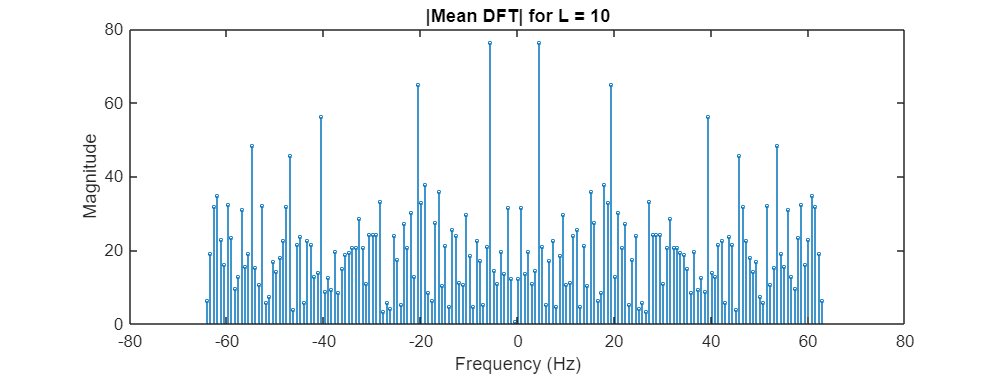

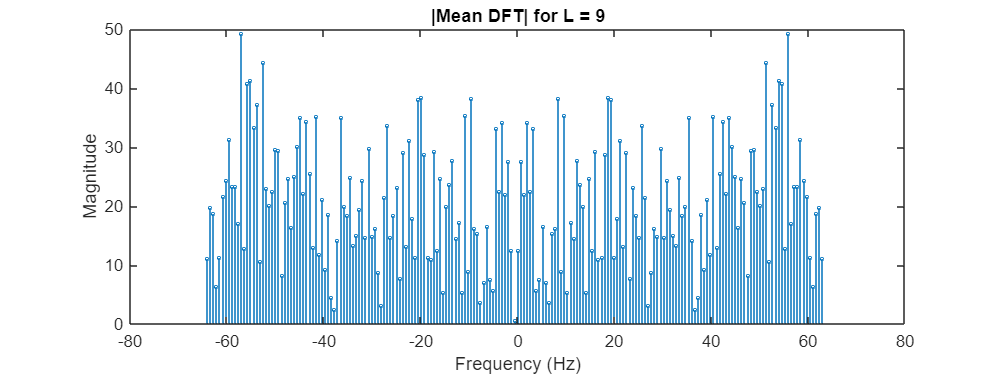

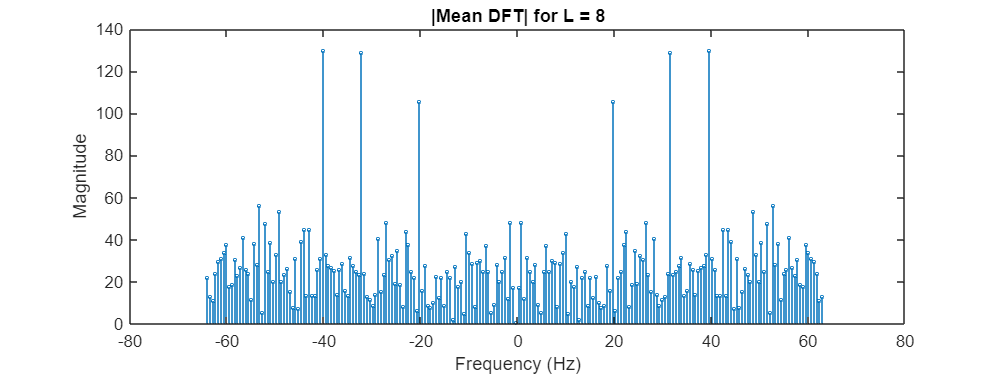

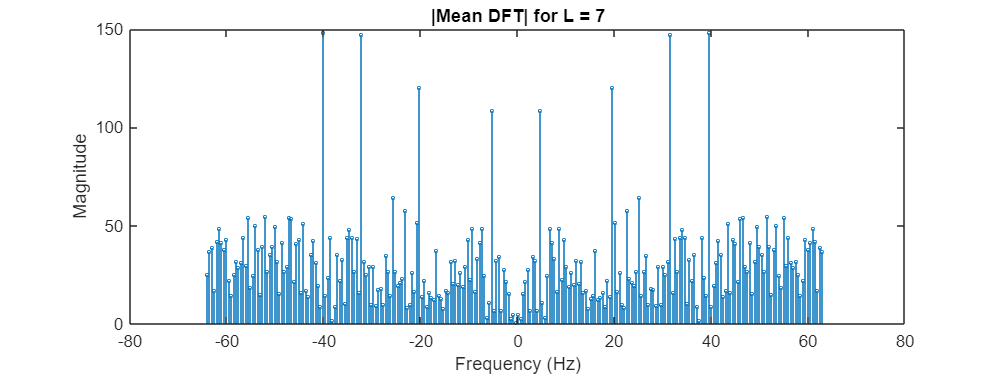

N = 1792; 
for L = 14:-1:1 
    K = floor(N/L); 
    subsets = cell(1, L);
    
    for i = 1:L
        subsets{i} = xn_test((i-1)*K+1: i*K);
    end
    
    % Apply dft for each subset
    dft_sub = cell(1, L);
    for i = 0:L-1
        dft_sub{i+1} = fftshift(fft(subsets{i+1},K));
    end
    
    % Calculate the arithmetic mean
    mean = zeros(1, K);
    for i = 1:L
        mean = mean + dft_sub{i};
    end
    mean = mean / L;

    % Create a frequency axis
    freq = linspace(-f/2, f/2-1, K);
    
    % Plot the magnitude of the mean DFT
    figure('Position', [100, 100, 800, 300]);
    stem(freq, abs(mean), 'MarkerSize', 2);
    title(['|Mean DFT| for L = ', num2str(L)]);
    xlabel('Frequency (Hz)');
    ylabel('Magnitude');

end

**6.**

_

_

_

## Interpolation

**1.**

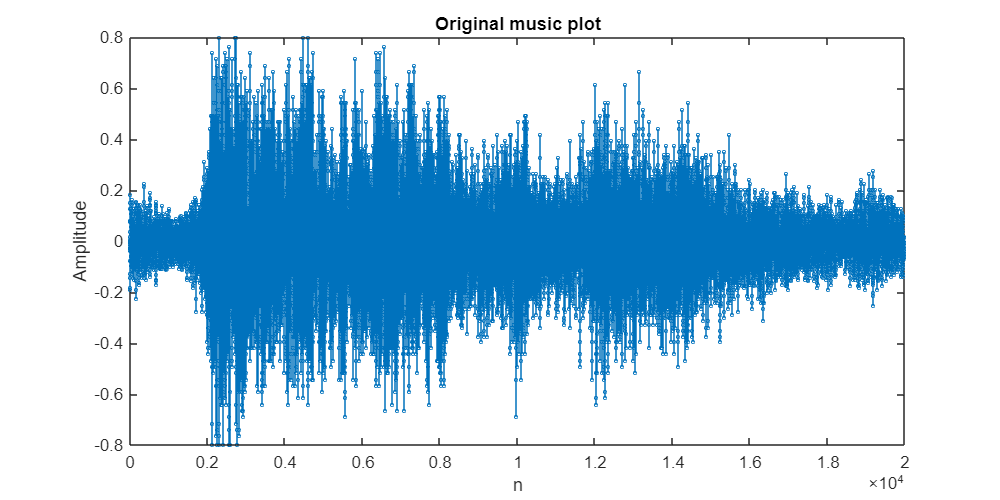

load handel
figure('Position', [100,100,800,400])
stem(y(1:20000), 'MarkerSize', 2);
title('Original music plot');
xlabel('n');
ylabel('Amplitude');

**2.**

x1 = y(1:20000);
x2 = x1(1:2:20000);
x3 = x1(1:3:20000);
x4 = x1(1:4:20000);
N=20000;

**3.**

*(a) K=1*

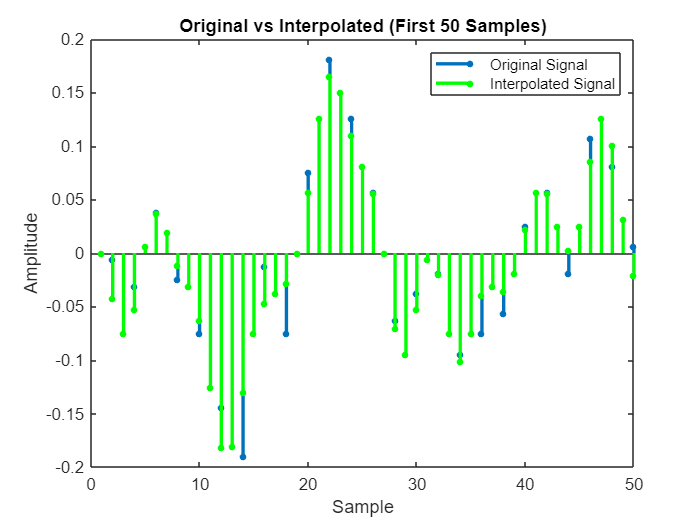

% Take dft of x2
X2 = fft(x2,N/2);
K = 1; Xz = zeros(N,1); 

% Create Xz for even DFT
Xz(1:N/4) = X2(1:N/4);
Xz(N/4 + 1) = X2(N/4 + 1) / 2;
Xz(N/4 + 1 + K * N/2) = X2(N/4 + 1) / 2;
Xz(N/4 + 2 + K * N/2:end) = X2(N/4 + 2:end);

% re create the interpolated signal
x_new = ifft(Xz);
x_new = (K + 1) * x_new;

time = 1:50;

% Plot both signals in the same figure
figure;
%original
stem(time, x1(1:50), 'o', 'LineWidth', 2, 'MarkerSize', 2);
hold on;
%interpolated
stem(time, x_new(1:50), 'g', 'LineWidth', 2, 'MarkerSize', 2);
hold off;

title('Original vs Interpolated (First 50 Samples)');
xlabel('Sample');
ylabel('Amplitude');
legend('Original Signal', 'Interpolated Signal');

diff = x_new(1:(K + 1)*(N/2- 1) + 1) - x1(1:(K + 1)*(N/2 - 1) + 1);
norm_2 = norm(diff, 2);

fprintf('2-norm of the error: %.4f\n', norm_2);

2-norm of the error: 6.1447


*(b) K=2*

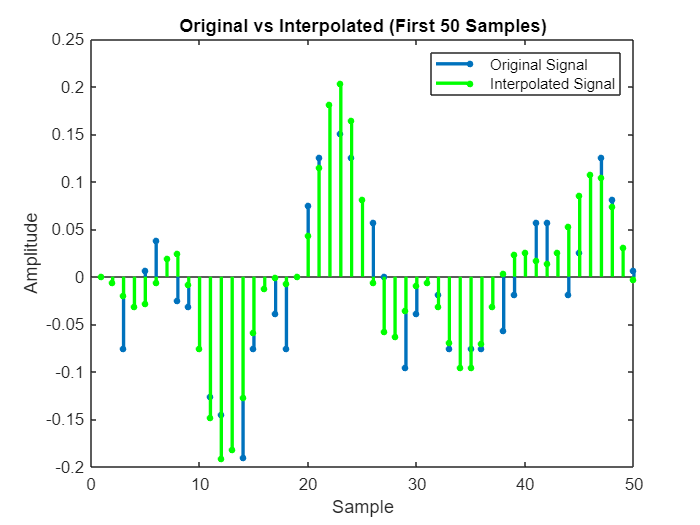

% Take dft of x3
l3 = ceil(N/3);
X3 = fft(x3,l3);
K = 2;
Xz = zeros(N,1);

Xz(1:(l3+1)/2) = X3(1:(l3+1)/2);
Xz((l3+1)/2 +  K * l3:end) = X3((l3+1)/2 + 1:end);

x_new = ifft(Xz, N);
x_new = (K + 1) * x_new;

t = 1:50;
figure;
stem(t, x1(1:50), 'o', 'LineWidth', 2, 'MarkerSize',2); % Original signal
hold on;
stem(t, x_new(1:50), 'g', 'LineWidth', 2, 'MarkerSize',2); % Interpolated signal

title('Original vs Interpolated (First 50 Samples)');
xlabel('Sample');
ylabel('Amplitude');

legend('Original Signal', 'Interpolated Signal');

diff= x_new(1:(K + 1) * (l3 - 1) + 1) - x1(1:(K + 1) * (l3 - 1) + 1);
norm_2 = norm(diff, 2);

fprintf('2-norm of the difference between the signals: %.4f\n', norm_2);

2-norm of the difference between the signals: 10.1872


*(c) K=3*

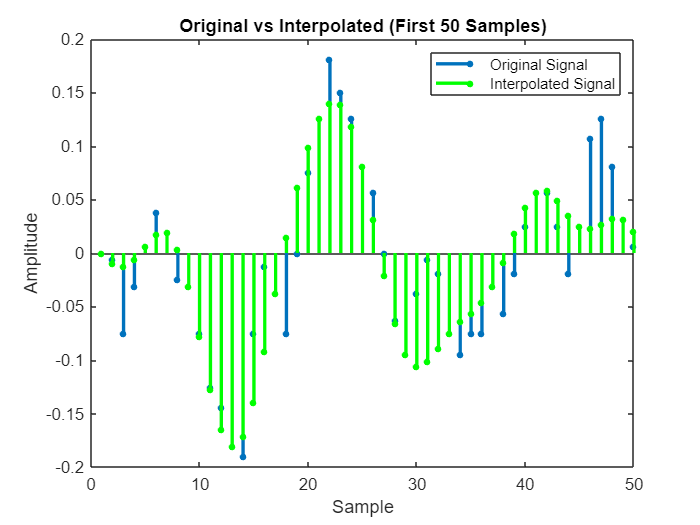

X4 = fft(x4,N/4);
N2 = N/8;
K = 3;

Xz = zeros(N,1);
Xz(1:N2) = X4(1:N2);
Xz(N2 + 1) = X4(N2 + 1) / 2;
Xz(N2 + 1 + K * N/4) = X4(N2 + 1) / 2;
Xz(N2 + 2 + K * N/4:end) = X4(N2 + 2:end);

x_new = ifft(Xz, N);
x_new = (K + 1) * x_new;

t = 1:50;

figure;
stem(t, x1(1:50), 'o', 'LineWidth', 2, 'MarkerSize',2); % Original signal
hold on; 
stem(t, x_new(1:50), 'g', 'LineWidth', 2, 'MarkerSize',2); % Interpolated signal
hold off; 
title('Original vs Interpolated (First 50 Samples)');
xlabel('Sample');
ylabel('Amplitude');

% Add a legend to differentiate the signals
legend('Original Signal', 'Interpolated Signal');

diff = x_new(1:(K + 1) * (N/4 - 1) + 1) - x1(1:(K + 1) * (N/4 - 1) + 1);
norm_2 = norm(diff, 2);
fprintf('2-norm of the difference between the signals: %.4f\n', norm_2);

2-norm of the difference between the signals: 23.4998


*(d)*